# mstle_phsdstrbtn analysis

Copyright © 2020 Yuichi Takeuchi

## initialization

clear; clc

## metainfo

ID = 'LTR1_82_83';
metainfo = {
    'AP', 190403, 2, 1, [82 83], [7 7]; % [22 14] % prefix, date, expNo1, expNo2, LTR, specific ch
    'AP', 190404, 1, 1, [82 83], [7 7];
    'AP', 190405, 1, 1, [82 83], [7 7];
    };

## path

addpath(genpath('helper'))
addpath(genpath('lib'))

## Downsampling and channel reorganization

for i = 1:size(metainfo,1)
    ds_Takeuchi3dual_2A1D_500_to_500(metainfo{i,1}, metainfo{i,2}, metainfo{i,3}, metainfo{i,4})
end

dat file preparations...
processing AP_190130_exp1_1.dat
extracting a digital channel...
Extracting 63 ch from AP_190130_exp1_1.dat ...
Extracting channels...
1 of 6 chunks
2 of 6 chunks
3 of 6 chunks
4 of 6 chunks
5 of 6 chunks
6 of 6 chunks
Extraction done.
done.
extracting analog input channels...
Extracting 61 ch from AP_190130_exp1_1.dat ...
Extracting channels...
1 of 6 chunks
2 of 6 chunks
3 of 6 chunks
4 of 6 chunks
5 of 6 chunks
6 of 6 chunks
Extraction done.
Extracting 62 ch from AP_190130_exp1_1.dat ...
Extracting channels...
1 of 6 chunks
2 of 6 chunks
3 of 6 chunks
4 of 6 chunks
5 of 6 chunks
6 of 6 chunks
Extraction done.
done.
headstage inputs...
Extracting 2   1   3   5   6   4   8   7   9  11  12  10  14  13  15  17  16  18  20  21  19  23  22  24  26  25  27  29  30  28 ch from AP_190130_exp1_1.dat ...
Extracting channels...
1 of 6 chunks
2 of 6 chunks
3 of 6 chunks
4 of 6 chunks
5 of 6 chunks
6 of 6 chunks
Extraction done.
done.
removing DC shifts from analog channel

clear i

## Get timestamps of seizure induction (digital channel bit 0)

% get timestamps of seizure induction, detections of rat 1, rat2 
RecInfo = cell(1, size(metainfo,1));
DataStruct = cell(1, size(metainfo,1));
for i = 1:size(metainfo,1)
    [tmpRecInfo] = getRecInfo(metainfo{i,1}, metainfo{i,2}, metainfo{i,3}, metainfo{i,4}, metainfo{i,5}, 500);
    [tmpDataStruct] = getDataStruct(tmpRecInfo);
    RecInfo{i} = tmpRecInfo;
    DataStruct{i}(1) = tmpDataStruct;
    DataStruct{i}(2) = tmpDataStruct;
end
save(['tmp/' ID '_RecInfo.mat' ], 'RecInfo')
% for i = 1:size(metainfo, 1)
%     DataStruct{1,i}(2) = DataStruct{1,i}(1);
% end
save(['tmp/' ID '_DataStruct.mat'], 'DataStruct')
clear i tmpRecInfo tmpDataStruct

## Manual curation of timestamp1

cidx = {
    1, 1, [], repmat([1 0],1,4);
    1, 2, [7 8], repmat([0 1],1,3);
    2, 1, [1 2], repmat([1 0],1,3);
    2, 2, [], repmat([0 1],1,4);
    };
load(['tmp/' ID '_DataStruct.mat'], 'DataStruct')
% orgTb = readtable('../notes/FigureS9_Fg624_ClosedLoopStim.csv');
for i = 1:size(cidx, 1)
    DataStruct{1,cidx{i,1}}(cidx{i,2}).Timestamp{1, 1}(cidx{i,3},:) = [];
    DataStruct{1,cidx{i,1}}(cidx{i,2}).TimestampMin(cidx{i,3},:) = [];
%     idxslct = ~orgTb.LTR == metainfo{i,5}(cidx{i,2}) & orgTb.expNo1 == metainfo{i,3}(cidx{i,1}) & orgTb.expNo2 == metainfo{i,4}(cidx{i,1});
    DataStruct{1,cidx{i,1}}(cidx{i,2}).idxslct = cidx{i,4};
end
save(['tmp/' ID '_DataStruct_curated.mat'], 'DataStruct')
clear cidx i

## Trial file extraction, Filtering, define detection timestamps

for i = 1:size(metainfo,1)
    [flag] = cut_postInductionTime_Takeuchi3_dual(RecInfo{i}, DataStruct{i});
end

start analysis...
AP_190130_exp1_1_LFP500_1.dat
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
AP_190130_exp1_1_LFP500_2.dat
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
done
Elapsed time is 0.204509 seconds.
start analysis...
AP_190130_exp1_1
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
AP_190130_exp1_1
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
done
Elapsed time is 0.062015 seconds.
start analysis...
AP_190204_exp1_1_LFP500_1.dat
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
AP_190204_exp1_1_LFP500_2.dat
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
done
Elapsed time is 0.169358 seconds.
start analysis...
AP_190204_exp1_1
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
AP_190204_exp1_1
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
done
Elapsed time is 0.051423 seconds.


clear i flag

## Circular phase analysis

RatNo: 1


fldrInfoadc = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 4.558254e-01


mu = 2.134236e+00


rayleigh test


   1



MI = 2.5806

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 3.696787e-01


mu = 2.016462e+00


rayleigh test


   1



MI = 3.0087

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 5.961706e-02


mu = 1.444053e+00


rayleigh test


   0



MI = 0.7669

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 2.260706e-01


mu = -2.544287e-01


rayleigh test


   1



MI = 1.3625

RatNo: 2


fldrInfoadc = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.305627e-01


mu = 1.874417e+00


rayleigh test


   1



MI = 4.8324

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.052149e-01


mu = 1.833552e+00


rayleigh test


   1



MI = 3.9551

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.608087e-01


mu = 1.966198e+00


rayleigh test


   1



MI = 6.4483

RatNo: 1


fldrInfoadc = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 3.384604e-01


mu = 1.939047e+00


rayleigh test


   1



MI = 1.4000

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 1.614611e-01


mu = -3.982204e-01


rayleigh test


   1



MI = 1.1522

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 3.312271e-01


mu = 1.925601e+00


rayleigh test


   1



MI = 1.9647

RatNo: 2


fldrInfoadc = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.513509e-01


mu = 2.115892e+00


rayleigh test


   1



MI = 6.2198

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 7.302239e-01


mu = 1.770558e+00


rayleigh test


   1



MI = 3.9749

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.814733e-01


mu = 2.102288e+00


rayleigh test


   1



MI = 8.7612

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 9.784304e-01


mu = 2.126461e+00


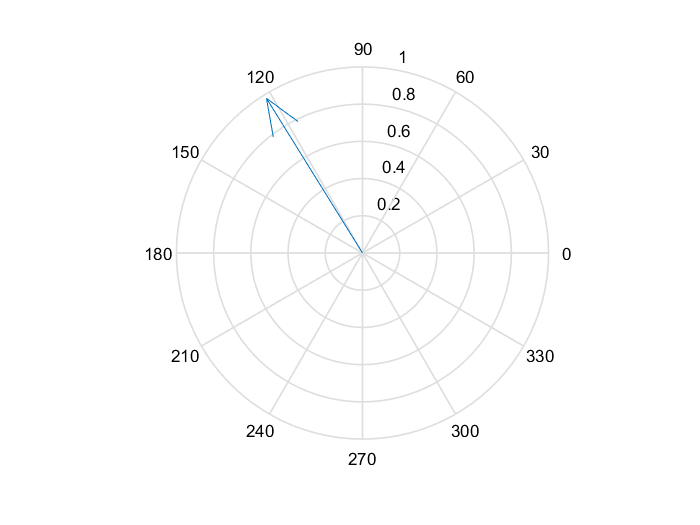

rayleigh test


   1



MI = 7.5610

%% ...analysis of intrinsic LFP phase
for i = 1:size(metainfo,1) % for by dat file
    % extract HPC ch for instantaneous phase
%     FreqTb = [1,4;4,12;12,30;30,45;45,80;80,300];
    drtn = 20; % in second
    sr = 500;
    threshold = 1000;
    FreqTb = [10 25];
    CField = {'seizure band'};
    Data = DataStruct{i};
    for RatNo = 1:length(Data) % for by rat no      
%         Data = DataStruct(RatNo);
%         disp(datfilename)
        fprintf('RatNo: %d\n', RatNo)
        fldrInfolfp = dir(['tmp/' Data(RatNo).datafilenamebase '_LFP500_' num2str(RatNo) '_trial*']);
        fldrInfoadc = dir(['tmp/' Data(RatNo).datafilenamebase '_adc_' num2str(RatNo) '_trial*'])
        for TrialNo = 1:length(fldrInfolfp)
            
            % find detection time stamps
            madc = memmapfile(['tmp/' fldrInfoadc(TrialNo).name], 'format', 'int16');
            dataadc = madc.data(1:drtn*sr);
            dtctlogical = dataadc > threshold;
            [~,tempR,~] = ssf_FindConsecutiveTrueChunks(dtctlogical');
            dtctn = uint64(tempR)';
            
            % data retrieval
            mlfp = memmapfile(['tmp/' fldrInfolfp(TrialNo).name], 'format', 'int16');
            lfpdata = reshape(mlfp.data, 30, []);
            lfpdata1ch = lfpdata(metainfo{i,6}(RatNo),1:drtn*sr); % channel extraction
            for bandNo = 1:numel(CField)
                disp(bandNo)
                tmpdata = filtf_LowPassButter3(lfpdata1ch, FreqTb(bandNo,2), 3, sr);
                FltdLFP = filtf_HighPassButter3(tmpdata, FreqTb(bandNo,1), 3, sr);
                y = hilbert(FltdLFP);
                phase = angle(y) + pi;
                
                InstantaneousPhase = phase(dtctn);
                
                % circular histograph
                edges = linspace(0, 2*pi, 360);
                [N, edges] = histcounts(InstantaneousPhase,edges);
                N = [N 0];
                
                polarhistogram(InstantaneousPhase, 12)
                print(['polarhist_' num2str(i) '_' num2str(RatNo) '_' num2str(TrialNo) '.png'], '-dpng')
                
                r = circ_r(edges, N); % r = circ_r(alpha, w, d, dim)
                fprintf('r = %d\n', r)
                
                [mu, ~, ~] = circ_mean(edges, N); % [mu, ul, ll] = circ_mean(alpha, w, dim)
                fprintf('mu = %d\n', mu)
                
                U = r*cos(mu);
                V = r*sin(mu);
                
                compass(U,V)
                print(['compass_' num2str(i) '_' num2str(RatNo) '_' num2str(TrialNo) '.png'], '-dpng')
                
%                 stats = circ_stats(edges, N); % stats = circ_stats(alpha, w, d)
                
                % Rayleigh test
                [pval, ~] = circ_rtest(edges, N); % [pval, z] = circ_rtest(alpha, w, d)
                disp('rayleigh test')
                if pval < 0.05
                    disp(true)
                else
                    disp(false)
                end
                
                Count = sum(reshape(N, 20, 18)); % modulation index
                meanCount = mean(Count,2);
                [maxCount, ~] = max(Count);
                [minCount, ~] = min(Count);
                if abs(maxCount - meanCount) > abs(minCount - meanCount)
                    diffCount = maxCount - meanCount;
                else
                    diffCount = minCount - meanCount;
                end
                MI = abs(diffCount/meanCount)
            end
        end
    end
end

## calc MRV per animal


% introduce delay 0, 20, 40, 60

## plot and graph output